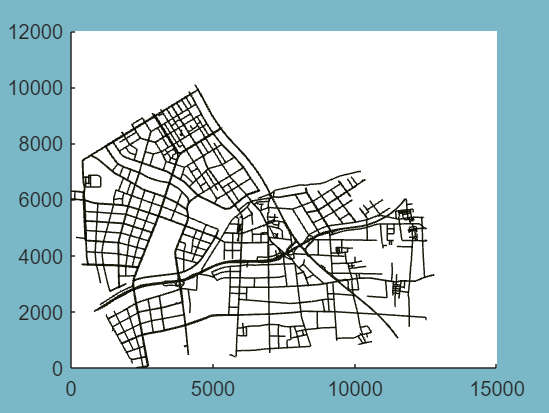

fig = figure;
set(fig,'Color',[0.4 0.6 0.65]*1.2) % 深蓝灰,更蓝
hold on
keys = entity_dict.keys;
for i  = 1:length(keys)
    entity = entity_dict{keys(i)};
    
    if isa(entity,'Lane_SUMO')
        if ~strncmp(entity.id,':',1)
            shape = entity.shape;
            plot(shape(:,1),shape(:,2),"Color",[0.1 0.1 0.05])
        end
    elseif isa(entity,'Junction_SUMO')
        shape = entity.shape;
        fill(shape(:,1),shape(:,2),'r','FaceAlpha',0.3)
    end
       
end
hold off

ax = gca;

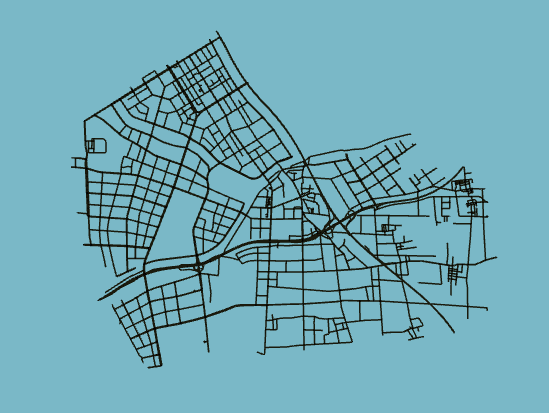

axis equal
axis auto
axis off

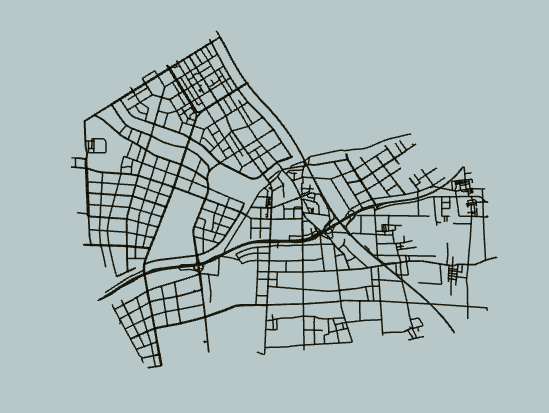

color = [0.6 0.65 0.65]*1.2;
set(gca,'Color',color) % 
set(fig,'Color',color) % 深蓝灰,更蓝
set(fig, 'InvertHardcopy', 'off');
% print(fig,'road_network','-djpeg','-r600');
exportgraphics(ax,'road_network.jpg',Resolution=600,BackgroundColor=color);

xlimit = get(gca, 'XLim');
ylimit = get(gca, 'YLim');
save('coords.mat', 'xlimit', 'ylimit');

img = imread('road_network.jpg');
load('coords.mat', 'xlimit', 'ylimit');

radius = 200;
ego.pos

ans = 1.0e+03 *

    3.5661    5.9744         0


fig2 = figure

fig2 =   Figure (29) - 属性:

      Number: 29
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 444 560 420]
       Units: 'pixels'

  显示 所有属性


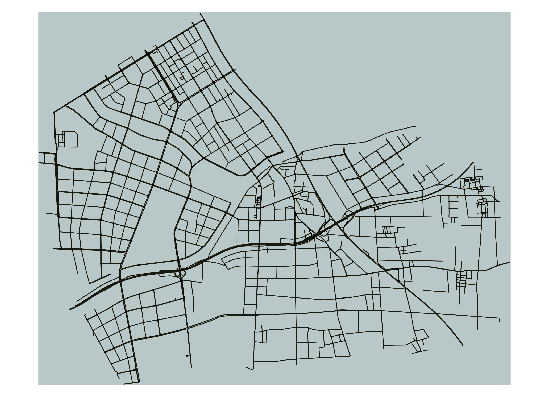

imshow(img)
hold on
scatter(ego.pos(1),ego.pos(2),'r','filled')

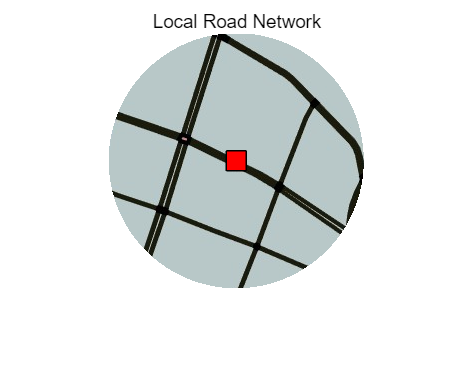

% 获取图像大小
[imgHeight, imgWidth, ~] = size(img);

% 计算坐标到像素的转换比例
xScale = imgWidth / (xlimit(2) - xlimit(1));
yScale = imgHeight / (ylimit(2) - ylimit(1));

% 计算显示区域在图像中的像素坐标
xCenterPixel = (ego.pos(1) - xlimit(1)) * xScale;
yCenterPixel = (ylimit(2) - ego.pos(2)) * yScale;
radiusPixel = radius*3 * xScale; % 假设 x 和 y 方向的比例相同

% 计算显示区域的边界像素坐标
xMinPixel = max(1, round(xCenterPixel - radiusPixel));
xMaxPixel = min(imgWidth, round(xCenterPixel + radiusPixel));
yMinPixel = max(1, round(yCenterPixel - radiusPixel));
yMaxPixel = min(imgHeight, round(yCenterPixel + radiusPixel));
localWidth = xMaxPixel - xMinPixel+1;
localHeight = yMaxPixel - yMinPixel+1;

carPos = [xCenterPixel-xMinPixel,yCenterPixel-yMinPixel];

% 截取显示区域
localArea = img(yMinPixel:yMaxPixel, xMinPixel:xMaxPixel, :);
% 创建一个遮罩
[X, Y] = meshgrid(1:localWidth, 1:localHeight);
mask = sqrt((X - carPos(1)).^2 + (Y - carPos(2)).^2) <= radiusPixel;

% 显示局部区域
figure;
imageShow = imshow(localArea);
set(imageShow,'AlphaData',mask)
hold on
h=fill(carPos(1)+10*[1,1,-1,-1],carPos(2)+10*[-1,1,1,-1],'r');
hold off
title('Local Road Network');